syms x y z
f = x ^ 2 * exp(sym(1)) ^ (y * z ^ 2)

$$f = x^{2}\,{\mathrm{e}}^{y\,z^{2}}$$

g = -(gradient(f, [x, y, z]))

$$g = \left(\begin{array}{c} -2\,x\,{\mathrm{e}}^{y\,z^{2}}\\ -x^{2}\,z^{2}\,{\mathrm{e}}^{y\,z^{2}}\\ -2\,x^{2}\,y\,z\,{\mathrm{e}}^{y\,z^{2}} \end{array}\right)$$

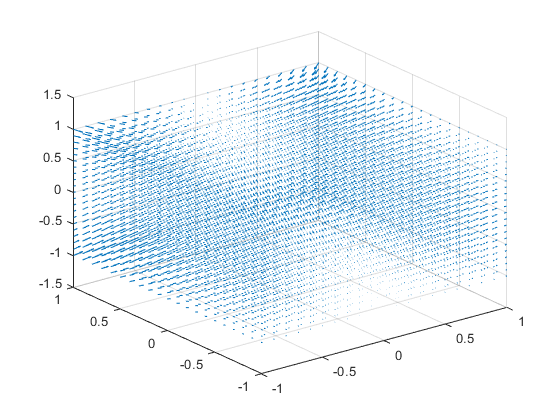

[X, Y, Z] = meshgrid(-1:.1:1,-1:.1:1,-1:.1:1);
G1 = subs(g(1),[x y z],{X,Y,Z});
G2 = subs(g(2),[x y z],{X,Y,Z});
G3 = subs(g(3),[x y z],{X,Y,Z});
quiver3(X,Y,Z,G1,G2,G3)